# **Supplementary: Squid biomass increase is not explain by rising temperature but rather loss of top predators.**

Rémy Denéchère <remy.denechere@proton.me>

## Initialisation 

clear all
clf 

% Create directory to save figure
save_dir = '../Fig/';
if ~exist(save_dir)
    mkdir(save_dir)
end 

figsave = true;

## Effect of large pelagic fishing on squid feeding level and mortality in a shallow system

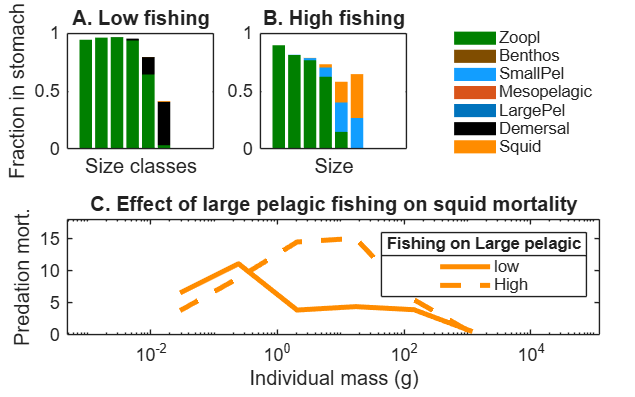

if exist("fig1")
    clear fig1
end

fig1 = figure();

t = tiledlayout(2, 3, "TileSpacing", "loose", "Padding", "compact");
% title(t, 'Effect of Large pelagic fishing on squid in the Open Ocean')

% set up range of parameters: ---------------------------------------------
depth = 50;                                   % Depth in m                                           
Zoo_prod = 100;                                 % Zooplankton production (g ww m-2 yr -1)           
param = baseparameters();                       % Create parameter structure
param = baseparam_depth(param, depth);          % Create depth related parameters
param.K = [Zoo_prod  Zoo_prod  0  0];           % Define productivity for each resouce (based on van Denderen 2021)

%! Calculation at low fishing intensity : ----------------------------------
% Calculate size-based fishing: 
param.Fi = [0.1, 0, 0.1, 0.1, 0.1];             % Fishing intensity for each group with a constant fishing
F = [];
for fi = 1:param.nSpecies
    F = [F, param.Fi(fi) * (1+(param.wc(param.ix1(fi):param.ix2(fi))...
        ./(param.wu(param.ix2(fi))*0.05)).^(-3)).^(-1)];
end
param.F = F';

% Define Initial Conditions 
param.y0 = [0.1*param.K 0.01*param.B0]; 
if depth < param.mesop % no meso in shallow areas. 
    param.y0(param.ix1(2):param.ix2(3))=0;        
end
results = poem(param);

% Plot Panel A: Low fishing feeding level
nexttile
plotdiet_squid(param, results, false)
ylabel('Fraction in stomach')
xlabel('Size classes')
title('A. Low fishing')
set(gca, 'FontSize', 11)
nexttile(4, [1, 3])
plotmort_squid(param, results, '-')
title('C. Effect of large pelagic fishing on squid mortality')

%! Calculation at low fishing intensity : ----------------------------------
depth = 2000;  % 250                                                
Zoo_prod = 100;
param = baseparameters();
param = baseparam_depth(param, depth);
param.K = [Zoo_prod  Zoo_prod  0  0];

% Calculate size-based fishing: 
param.Fi = [0.1, 0, 3, 0.1, 0.1];
F = [];
for fi = 1:param.nSpecies
    F = [F, param.Fi(fi) * (1+(param.wc(param.ix1(fi):param.ix2(fi))...
        ./(param.wu(param.ix2(fi))*0.05)).^(-3)).^(-1)];
end
param.F = F';

% Define Initial Conditions 
param.y0 = [0.1*param.K 0.01*param.B0]; 
if depth < param.mesop % no meso in shallow areas. 
    param.y0(param.ix1(2):param.ix2(3))=0;        
end
results = poem(param);

% Plot Panel B: feeding level at high fishing intensity
nexttile(2)
plotdiet_squid(param, results, true)
xlabel('Size')
title('B. High fishing')
set(gca, 'FontSize', 11)

% Plot Panel C: Squid mortality at high fishing intensity
nexttile(4, [1, 3])
plotmort_squid(param, results, '--')
xlabel('Individual mass (g)')
leg = legend('low', 'High'); 
title(leg, 'Fishing on Large pelagic') 
set(gca, 'FontSize', 11)

%! Save figure
if figsave
    save_graph(fig1, 'pdf', [save_dir 'F_mort_squid_Shallow'], 16, 10)
end

## Supplement B: Effect of varying 𝑄10 assumptions between max consumption, clearance rate and metabolism for squid.


%% Try different Q10 for Standard metaolism and consumption: 
if exist("fig2")
    clear fig2
end

fig2 = figure();

depth = [50 2000];
Zoo_prod = 150; % linspace(5, 150, 10);
param = baseparameters();
T = linspace(-2, 2, 10);
TEMP = ones(10, param.nSpecies); 
param.K = [Zoo_prod Zoo_prod 0 0]; 
param.y0 = [0.1*param.K 0.01*param.B0];

Q10  =  [1.88  1.88   1.5];   % Q10 for consumption.
Q10m =  [1.5   1.88   1.5];  % Q10 for Standard metabolism. 
linestyle = {':', '-', '--'};

tlayout = tiledlayout(1, 2, Padding="compact", TileSpacing="compact");

for dp = 1:2
    nexttile
    param = baseparam_depth(param, depth(dp));
    if depth(dp) < 250
        param.y0(param.ix1(2):param.ix2(2)) = 0;
    end
    hold on 
    for i = 1:3
        param.Q10(param.ix1(5):param.ix2(5)) = Q10(i);
        param.Q10m(param.ix1(5):param.ix2(5)) = Q10m(i);
        % Loop depth: ------------------------------------------    
        % Loop Temperature: --------------------------------
        for t = 1:10
            param = baseparam_temp(param, 4, T(t)+10);                     % Assumption that reference temperature for the system = 10
            results = poem(param);
            y = mean(results.y(end-40:end,:));

            for ii = 1:param.nSpecies
                TEMP(t,ii) = sum(y(param.ix1(ii):param.ix2(ii)));
            end
        end
        if dp == 1 
            visibility = ["off", "off", "off", "on", "off"];
        else 
            if i == 2
                visibility = ["on", "on", "on", "on", "on"];
            else
                visibility = ["off", "off", "off", "off", "off"];
            end 
        end 

        for ii = 1:param.nSpecies
            idx = TEMP(:,ii) > 0 ; 
            plot(T(idx), TEMP(idx,ii), 'LineWidth', param.LWidth(ii),...
                'color', param.Color(ii, :), 'LineStyle', linestyle{i}, ...
                'HandleVisibility', visibility(ii));
        end 
        title(['Depth = ', num2str(depth(dp)), ' m'])
        set(gca, 'YScale', 'log', 'Ylim', [0.1 100]) % 

        if dp == 1
            Leg = legend('Q_{10} > Q_{10m} ', 'Q_{10} = Q_{10m}', 'Q_{10} < Q_{10m}', 'Location', 'southeast');
        else
            Leg = legend(param.SpId{:}, 'Location', 'northwest');
        end  
    end
    hold off
    Leg.Box = 'off'; Leg.EdgeColor = 'none'; Leg.Color = 'none';
end

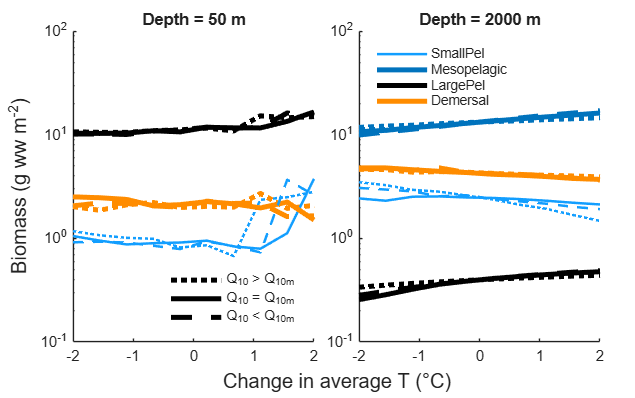



xlabel(tlayout, 'Change in average T (°C)')
ylabel(tlayout, 'Biomass (g ww m^{-2})')

save_graph(fig2, 'pdf', [save_dir,'Sens_temp_Q10'], 16, 10)

## Supplement C: Effect of varying 𝑄10 assumptions between fish and squid


%% Try different Q10 for fish and Squid: 
if exist("fig3")
    clear fig3
end

fig3 = figure();

depth = [50 2000];
Zoo_prod = 150; % linspace(5, 150, 10);
param = baseparameters();
T = linspace(-2, 2, 10);
TEMP = ones(10, param.nSpecies); 
param.K = [Zoo_prod Zoo_prod 0 0]; 
param.y0 = [0.1*param.K 0.01*param.B0];

Q10  =  [1   1.88   2.5];   % Q10 for consumption.
Q10m =  [1   1.88   2.5];  % Q10 for Standard metabolism. 
linestyle = {':', '-', '--'};

tlayout = tiledlayout(1, 2, Padding="compact", TileSpacing="compact");

for dp = 1:2
    nexttile
    param = baseparam_depth(param, depth(dp));
    if depth(dp) < 250
        param.y0(param.ix1(2):param.ix2(2)) = 0;
    end
    hold on 
    for i = 1:3
        param.Q10(param.ix1(5):param.ix2(5)) = Q10(i);
        param.Q10m(param.ix1(5):param.ix2(5)) = Q10m(i);
        % Loop depth: ------------------------------------------    
        % Loop Temperature: --------------------------------
        for t = 1:10
            param = baseparam_temp(param, 4, T(t)+10);                     % Assumption that reference temperature for the system = 10
            results = poem(param);
            y = mean(results.y(end-40:end,:));

            for ii = 1:param.nSpecies
                TEMP(t,ii) = sum(y(param.ix1(ii):param.ix2(ii)));
            end
        end
        if dp == 1 
            visibility = ["off", "off", "off", "on", "off"];
        else 
            if i == 2
                visibility = ["on", "on", "on", "on", "on"];
            else
                visibility = ["off", "off", "off", "off", "off"];
            end 
        end 

        for ii = 1:param.nSpecies
            idx = TEMP(:,ii) > 0 ; 
            plot(T(idx), TEMP(idx,ii), 'LineWidth', param.LWidth(ii),...
                'color', param.Color(ii, :), 'LineStyle', linestyle{i}, ...
                'HandleVisibility', visibility(ii));
        end 
        title(['Depth = ', num2str(depth(dp)), ' m'])
        set(gca, 'YScale', 'log', 'Ylim', [0.1 100]) % 

        if dp == 1
            Leg = legend('Q_{10, Fish} > Q_{10, Squid} ', ...
                         'Q_{10, Fish} = Q_{10, Squid} ' , ...
                         'Q_{10, Fish} < Q_{10, Squid} ' , 'Location', 'southeast');
        else
            Leg = legend(param.SpId{:}, 'Location', 'northwest');
        end  
    end
    hold off
    Leg.Box = 'off'; Leg.EdgeColor = 'none'; Leg.Color = 'none';
end

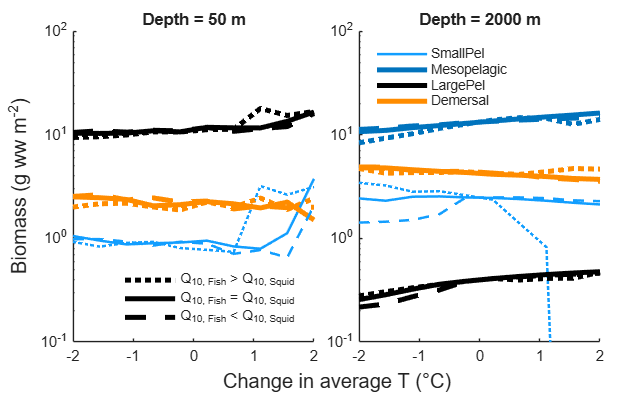



xlabel(tlayout, 'Change in average T (°C)')
ylabel(tlayout, 'Biomass (g ww m^{-2})')

save_graph(fig3, 'pdf', [save_dir,'Sens_temp_Q10_fish_and_Squid'], 16, 10)